# LiDARDRONE

# Drone Control with pid dynamics

MRK 1.5

17/5 integrated the imu in the simulation and rrt based on lidar measurement

________________________________

This file correspond to a single iteration of a single drone during its simulation

clc;
clear;
clear all;
clf;

#### Map definition and obstacles plot

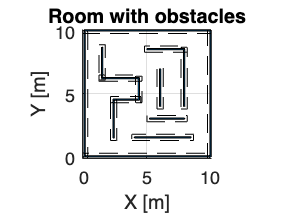

x_map_size = 10;
y_map_size = 10;

[obstacles, inflated_obstacles] = map_definition;

figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Room with obstacles');
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);

## SIMULATION + RRT TREE GENERATION

Combined exploration movements

Drones set up with their specifications

n = 2; % Number of drones
Drone = struct(); %New struct

for i = 1:n % compute for each drone

    % Define drone specifications such as name and color
    drone_name = ['Drone_' num2str(i)];
    Drone.(drone_name).color = rand(1,3); %Drone and scanning color

    %RRT starting point position
    Drone.(drone_name).map = [5,5];
    %Drone.(drone_name).map = [rand() * x_map_size, rand() * y_map_size]; % first corresppond to the starting_point

    while isInObstacle(Drone.(drone_name).map,inflated_obstacles) == true
        % If the random starting point position is inside obstacles,
        % calculate another point
        Drone.(drone_name).map =[rand() * x_map_size, rand() * y_map_size];
    end

    Drone.(drone_name).RRT.step_size = 0.3;
    Drone.(drone_name).RRT.n_iterations = 10;
    Drone.(drone_name).RRT.epsilon = 0.5;
    Drone.(drone_name).RRT.minPts = 1;
    Drone.(drone_name).RRT.fov_drone = 2;
    Drone.(drone_name).RRT.parent_indices = 0;  % Indices numbers to link the points of the trees
    Drone.(drone_name).RRT.inflate = 0.15;
    Drone.(drone_name).RRT.imu_noise = 0.1;

    Drone.(drone_name).PID.Kp = 0.6; % componente proporzionale
    Drone.(drone_name).PID.Ki = 0.02; % componente integrale
    Drone.(drone_name).PID.Kd = 0.9; % componente derivativa
    Drone.(drone_name).PID.initial_vel = [0; 0];
    Drone.(drone_name).PID.max_speed = [1; 1]; % velocità massima consentita
    Drone.(drone_name).PID.max_acc = [1;1]; %accelerazione massima consentita


    %Lidar parameters specifications
    Drone.(drone_name).Lidar.lidar_angles = linspace(0, 360, 100);  % Number of rays [-]
    Drone.(drone_name).Lidar.scanning_lines = 100;
    Drone.(drone_name).Lidar.max_range = 3;                         % Maximum length measurement [m]
    Drone.(drone_name).Lidar.lidar_dist_res = 0.002; % Distance measurement resolution [m]
    Drone.(drone_name).Lidar.Drone_rel_position = [0,0];
    Drone.(drone_name).Lidar.scan_points = [];
    Drone.(drone_name).Lidar.scan_points_new = []; %for fusion with same drone scans
    Drone.(drone_name).Lidar.scan_dist_new = []; %for fusion with same drone scans
    Drone.(drone_name).Lidar.profile = [];
    Drone.(drone_name).Lidar.peaks = [];

end

nearest_points_tresshold = 0.05;
filtering_landmarks_threshold = 5;


START THE DRONES SIMULATION

% Simulation setup
SetUp.Dt = 0.1; % [s]
setUp.MaxTime = 30; % [s]

%Step 0 simulation
for i = 1:n
    drone_name = ['Drone_' num2str(i)];

    %first scan
    [~,~, Drone.(drone_name).Lidar.scan_points, Drone.(drone_name).Lidar.scan_dist] = Lidar_scan(obstacles, Drone.(drone_name).map, Drone.(drone_name).Lidar.lidar_angles, Drone.(drone_name).Lidar.max_range, Drone.(drone_name).Lidar.lidar_dist_res);
    Drone.(drone_name).count_pos = 1;
    %creating obstacles from scan
    obstacles_lidar = lidar_data_to_obstacles(Drone.(drone_name).Lidar.scan_points,Drone.(drone_name).RRT.epsilon,Drone.(drone_name).RRT.minPts);
    inflate = 0.15;
    inflated_obstacles_lidar = zeros(size(obstacles_lidar));
    for j = 1:height(obstacles_lidar)
        inflated_obstacles_lidar(j, 1) = obstacles_lidar(j, 1) - inflate; % x left shifted
        inflated_obstacles_lidar(j, 2) = obstacles_lidar(j, 2) - inflate; % y down shifted
        inflated_obstacles_lidar(j, 3) = obstacles_lidar(j, 3) + 2*inflate; % width
        inflated_obstacles_lidar(j, 4) = obstacles_lidar(j, 4) + 2*inflate; % height
    end
    
    %creating rrt treee
    [Drone.(drone_name).RRT.rrt_tree, parent_indices] = RRT_DRONE_NEW(Drone.(drone_name).RRT.step_size,Drone.(drone_name).RRT.n_iterations, Drone.(drone_name).RRT.fov_drone, inflated_obstacles_lidar, Drone.(drone_name).Lidar.scan_points, Drone.(drone_name).RRT.epsilon, Drone.(drone_name).RRT.minPts);
    farest = [0; 0];
    dist_farest = 0;
    for k=2:length(Drone.(drone_name).RRT.rrt_tree)
        temp_point = Drone.(drone_name).RRT.rrt_tree(k, :);
        if norm(Drone.(drone_name).RRT.rrt_tree(1, :) - Drone.(drone_name).RRT.rrt_tree(k, :)) > dist_farest
            dist_farest = norm(Drone.(drone_name).RRT.rrt_tree(1, :) - Drone.(drone_name).RRT.rrt_tree(k, :));
            farest = Drone.(drone_name).RRT.rrt_tree(k, :);
        end
    end
    correspondence = ismember(Drone.(drone_name).RRT.rrt_tree, farest, 'rows');
    index = find(all(correspondence, 2));
    Drone.(drone_name).RRT.points_rrt = [];
    while index ~= 0
        Drone.(drone_name).RRT.points_rrt = [Drone.(drone_name).RRT.rrt_tree(index, :); Drone.(drone_name).RRT.points_rrt];
        index = parent_indices(index);
    end

    %creating intermediates goals and final goal
    Drone.(drone_name).RRT.points = Drone.(drone_name).RRT.points_rrt';
    Drone.(drone_name).RRT.check_point_index = 2;
    Drone.(drone_name).RRT.final_pos = Drone.(drone_name).RRT.points(:, Drone.(drone_name).RRT.check_point_index);

    %initializing PID

    % Error variables
    Drone.(drone_name).PID.error_sum=0;
    Drone.(drone_name).PID.previous_error = 0;

    % Velocità iniziale e finale desiderate
    Drone.(drone_name).RRT.initial_vel = [0; 0];
    Drone.(drone_name).RRT.positions = []; % registro delle posizioni per la visualizzazione
    Drone.(drone_name).RRT.end_pos = [];
    imu_noise = 0.1;
    
    Drone.(drone_name).RRT.pos = Drone.(drone_name).RRT.points(:, 1);
    Drone.(drone_name).RRT.vel = Drone.(drone_name).PID.initial_vel;
    
    % continua finché non si raggiunge la destinazione
    
    proximity_threshold = 0.1;

    

end



## starting simulation




for t = 0:SetUp.Dt:setUp.MaxTime
    for i = 1:n
        drone_name = ['Drone_' num2str(i)];

        Drone.(drone_name).PID.error_pos = Drone.(drone_name).RRT.final_pos - Drone.(drone_name).RRT.pos;

        % Proportional component
        Drone.(drone_name).PID.control_p = Drone.(drone_name).PID.Kp * Drone.(drone_name).PID.error_pos;

        % Integral component
        Drone.(drone_name).PID.error_sum = Drone.(drone_name).PID.error_sum + Drone.(drone_name).PID.error_pos * SetUp.Dt;
        Drone.(drone_name).PID.control_i = Drone.(drone_name).PID.Ki * Drone.(drone_name).PID.error_sum;

        % Derivative component
        Drone.(drone_name).PID.derivative = (Drone.(drone_name).PID.error_pos - Drone.(drone_name).PID.previous_error) / SetUp.Dt;
        Drone.(drone_name).PID.control_d = Drone.(drone_name).PID.Kd * Drone.(drone_name).PID.derivative;

        Drone.(drone_name).PID.control_d = min(max(Drone.(drone_name).PID.control_d, -Drone.(drone_name).PID.max_speed), Drone.(drone_name).PID.max_speed);

        % Final control signal
        Drone.(drone_name).PID.control = Drone.(drone_name).PID.control_p + Drone.(drone_name).PID.control_i + Drone.(drone_name).PID.control_d;

        % Speed limitation
        Drone.(drone_name).PID.control = min(max(Drone.(drone_name).PID.control, -Drone.(drone_name).PID.max_acc), Drone.(drone_name).PID.max_acc);

        % Add IMU noise
        Drone.(drone_name).PID.control = Drone.(drone_name).PID.control + imu_noise * randn(2, 1);

        % Update velocity and position
        Drone.(drone_name).RRT.vel = Drone.(drone_name).RRT.vel + Drone.(drone_name).PID.control * SetUp.Dt;
        Drone.(drone_name).RRT.pos = Drone.(drone_name).RRT.pos + Drone.(drone_name).RRT.vel * SetUp.Dt;

        % Store position
        Drone.(drone_name).RRT.positions = [Drone.(drone_name).RRT.positions, Drone.(drone_name).RRT.pos];

        % Update previous error
        Drone.(drone_name).PID.previous_error = Drone.(drone_name).PID.error_pos;

        % Check if checkpoint reached
        if norm(Drone.(drone_name).RRT.pos - Drone.(drone_name).RRT.final_pos) <= proximity_threshold && Drone.(drone_name).RRT.check_point_index < length(Drone.(drone_name).RRT.points)
            % Update checkpoint
            Drone.(drone_name).RRT.check_point_index = Drone.(drone_name).RRT.check_point_index + 1;
            Drone.(drone_name).RRT.final_pos = Drone.(drone_name).RRT.points(:, Drone.(drone_name).RRT.check_point_index);
        end

        % Check if final point of RRT is reached
        if norm(Drone.(drone_name).RRT.pos - Drone.(drone_name).RRT.points(:, end)) <= proximity_threshold
            Drone.(drone_name).count_pos = Drone.(drone_name).count_pos + 1; % Update position index in map

            % Update absolute position in the map
            Drone.(drone_name).map(Drone.(drone_name).count_pos, 1) = Drone.(drone_name).map(Drone.(drone_name).count_pos - 1, 1) + Drone.(drone_name).RRT.points(1, end); % pos x rel
            Drone.(drone_name).map(Drone.(drone_name).count_pos, 2) = Drone.(drone_name).map(Drone.(drone_name).count_pos - 1, 2) + Drone.(drone_name).RRT.points(2, end); % pos y rel

            % Store final velocity
            Drone.(drone_name).RRT.final_velocity = Drone.(drone_name).RRT.vel;

            % Perform new scan
            [~, ~, Drone.(drone_name).Lidar.scan_points_new, Drone.(drone_name).Lidar.scan_dist_new] = Lidar_scan(obstacles, Drone.(drone_name).map(Drone.(drone_name).count_pos, :), Drone.(drone_name).Lidar.lidar_angles, Drone.(drone_name).Lidar.max_range, Drone.(drone_name).Lidar.lidar_dist_res);

            % Combine new scan with previous scans
            map1 = Drone.(drone_name).Lidar.scan_points; % historical point cloud
            map2 = Drone.(drone_name).Lidar.scan_points_new; % new point cloud to merge
            pos1 = Drone.(drone_name).map(Drone.(drone_name).count_pos - 1, :); % previous position
            pos2 = Drone.(drone_name).map(Drone.(drone_name).count_pos, :); % current position

            % Virtual points translation for map1
            virtual_points = [map1(:, 1) - Drone.(drone_name).RRT.pos(1), map1(:, 2) - Drone.(drone_name).RRT.pos(2)];

            % Compare point clouds and find common points
            common_points = point_cloud_compare(virtual_points, map2, proximity_threshold);

            % Average common points
            for pointer = 1:length(virtual_points)
                for index = 1:size(common_points, 1)
                    if common_points(index, 1) == pointer
                        virtual_points(pointer, 1) = (common_points(index, 2) + common_points(index, 5)) / 2;
                        virtual_points(pointer, 2) = (common_points(index, 3) + common_points(index, 6)) / 2;
                    end
                end
            end

            for pointer = 1:length(map2)
                for index = 1:size(common_points, 1)
                    if common_points(index, 4) == pointer
                        map2(pointer, 1) = (common_points(index, 2) + common_points(index, 5)) / 2;
                        map2(pointer, 2) = (common_points(index, 3) + common_points(index, 6)) / 2;
                    end
                end
            end

            % Combine point clouds
            [new_virtual_points, new_map2] = combine_point_clouds(virtual_points, map2);

            % Update scan points with merged map
            Drone.(drone_name).Lidar.scan_points = new_map2;
            Drone.(drone_name).Lidar.scan_points_new = [];

            % Update landmarks
            Res = 1;
            index = 1;
            Drone.(drone_name).Lidar.profile = [];
            Drone.(drone_name).Lidar.peaks = [];

            while index <= size(Drone.(drone_name).Lidar.scan_points, 1)
                if index <= Res || index > size(Drone.(drone_name).Lidar.scan_points, 1) - Res
                    Drone.(drone_name).Lidar.profile(index, 1) = 1;
                    Drone.(drone_name).Lidar.profile(index, 2) = 0;
                    Drone.(drone_name).Lidar.profile(index, 3) = 0;
                else
                    % Curvature
                    F = [Drone.(drone_name).Lidar.scan_points(index - Res, 1), Drone.(drone_name).Lidar.scan_points(index - Res, 2), 0];
                    G = [Drone.(drone_name).Lidar.scan_points(index, 1), Drone.(drone_name).Lidar.scan_points(index, 2), 0];
                    H = [Drone.(drone_name).Lidar.scan_points(index + Res, 1), Drone.(drone_name).Lidar.scan_points(index + Res, 2), 0];

                    f = norm(G - H);
                    g = norm(F - H);
                    h = norm(G - F);
                    A = norm(cross(H - F, G - F) / 2);
                    Drone.(drone_name).Lidar.profile(index, 1) = 4 * A / (f * g * h);

                    % PCA
                    X = [Drone.(drone_name).Lidar.scan_points(index - Res:index + Res, 1), Drone.(drone_name).Lidar.scan_points(index - Res:index + Res, 2)];
                    Covar = cov(X);
                    [~, D] = eig(Covar);

                    if D(1, 1) > D(2, 2)
                        Dm = D(1, 1);
                    else
                        Dm = D(2, 2);
                    end

                    Drone.(drone_name).Lidar.profile(index, 2) = Dm;

                    if Drone.(drone_name).Lidar.profile(index, 1) > thresshold
                        if Drone.(drone_name).Lidar.profile(index, 2) < thresshold
                            % Peak
                            Drone.(drone_name).Lidar.profile(index, 3) = 1;
                            Drone.(drone_name).Lidar.peaks = [Drone.(drone_name).Lidar.peaks; Drone.(drone_name).Lidar.scan_points(index, :)];
                        else
                            % Wall
                            Drone.(drone_name).Lidar.profile(index, 3) = 2;
                        end
                    else
                        Drone.(drone_name).Lidar.profile(index, 3) = 0;
                    end
                end
                index = index + 1;
            end

            % Add new RRT
            Drone.(drone_name).RRT.points = Drone.(drone_name).RRT.new_points;
            Drone.(drone_name).RRT.new_points = [];
            Drone.(drone_name).RRT.check_point_index = 2;
            Drone.(drone_name).RRT.final_pos = Drone.(drone_name).RRT.points(:, Drone.(drone_name).RRT.check_point_index);
        end
    end
end

Unrecognized function or variable 'thresshold'.

#### Map lidar scan to undestand the surroundings

% start = [rand() * x_map_size, rand() * y_map_size]; % absolute poi from wich the drone starts the simulation
% 
%  while isInObstacle(start, inflated_obstacles)   % if the drone is shipped into a wall, selcet a new possible point until it is a good hit
%         start = [rand() * x_map_size, rand() * y_map_size];
%  end

% For now test with a given point
start = [5, 8]; % absolute poi from wich the drone starts the simulation

lidar_position = start;
lidar_angles = linspace(0, 360, 100);  % 100 scanning lines
max_range = 2;
lidar_dist_res = 0.01; 
[point_abs,point_abs_clean, point_rel, dist_rel] = Lidar_scan(obstacles, lidar_position, lidar_angles, max_range, lidar_dist_res);


% Plot LiDAR result in relative envioment
plot(point_rel(:, 1), point_rel(:, 2), 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'black', 'MarkerSize', 5); % Plot ray
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
title('Lidar Relative point position');


img = imread('drone.jpg'); % Sostituisci con il percorso dell'immagine
imageWidth = 0.5; % Larghezza desiderata dell'immagine
imageHeight = 0.5; % Altezza desiderata dell'immagine
xPos = 0 - imageWidth/2; % Posizionamento sull'asse x
yPos = 0 - imageHeight/2; % Posizionamento sull'asse y

% Aggiungi l'immagine alla posizione specificata
image('CData', img, 'XData', [xPos, xPos + imageWidth], 'YData', [yPos, yPos + imageHeight]);


#### Build the RRT algorith to explore the space (ONE STEP TIME EXAMPLE)

% Parameter declaration
step_size = 0.3; 
n_iterations = 10; 
% goal_threshold = 0.5; 

epsilon = 0.5;
minPts = 1;
fov_drone = 2;


obstacles_lidar = lidar_data_to_obstacles(point_rel,1,1); %(coords, min distance tra punti per stesso cluster, min numero punti per cluster)
% Iinflation factor applied to the obstacles
inflate = 0.15;
inflated_obstacles_lidar = zeros(size(obstacles_lidar));
for i = 1:height(obstacles_lidar)
    inflated_obstacles_lidar(i, 1) = obstacles_lidar(i, 1) - inflate; % x iniziale spostato a sinistra
    inflated_obstacles_lidar(i, 2) = obstacles_lidar(i, 2) - inflate; % y iniziale spostato in basso
    inflated_obstacles_lidar(i, 3) = obstacles_lidar(i, 3) + 2*inflate; % larghezza aumentata
    inflated_obstacles_lidar(i, 4) = obstacles_lidar(i, 4) + 2*inflate; % altezza aumentata
end

[rrt_tree, parent_indices] = RRT_DRONE_NEW(step_size,n_iterations, fov_drone, inflated_obstacles_lidar, point_rel, epsilon, minPts);

%just for plots
rrt_abs_tree = [rrt_tree(:, 1) + start(1,1), rrt_tree(:, 2) + start(1,2)];

#### Plot the RRT

figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
%xlim([-0.10 x_map_size + 0.1]);
%ylim([-0.10 y_map_size + 0.1]);
title('RRT in relative map');
hold on;
PLOT_MAP(obstacles_lidar, inflated_obstacles_lidar, 10, 10);
RRT_PLOT(rrt_tree, parent_indices);
hold off;

% Da plottare in sistema assoluto?
figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
title('RRT in absolute map');
hold on;
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
RRT_PLOT(rrt_abs_tree, parent_indices);
hold off;

#### PID navigation

% Identify the farest point wrt the tree generated in the lidar reference
% frame
farest = [0; 0];
dist_farest = 0;
for k=2:length(rrt_tree)
    temp_point = rrt_tree(k, :);
    if norm(rrt_tree(1, :) - rrt_tree(k, :)) > dist_farest
        dist_farest = norm(rrt_tree(1, :) - rrt_tree(k, :));
        farest = rrt_tree(k, :);
    end
end
correspondence = ismember(rrt_tree, farest, 'rows');
index = find(all(correspondence, 2));
% reconstruct the path to make

#### Reconstruction of the path to reach the farest point

points_rrt = [];
while index ~= 0
    points_rrt = [rrt_tree(index, :); points_rrt];
    index = parent_indices(index);
end

points = points_rrt';

% Coefficienti PID -- METTERE IN FUNZIONE
Kp = 0.6; % componente proporzionale
Ki = 0.02; % componente integrale
Kd = 0.9; % componente derivativa

% Error variables
error_sum=0;
previous_error = 0;

final_pos = points(:, length(points));
% Velocità iniziale e finale desiderate
initial_vel = [0; 0];
max_speed = [1; 1]; % velocità massima consentita
max_acc = [1;1]; %accelerazione massima consentita
% Simulazione del controllo PID
t = 0; % tempo iniziale
positions = []; % registro delle posizioni per la visualizzazione
end_pos = [];
% Passo temporale (in secondi)
dt = 0.1;
imu_noise = 0.1;

% Posizione iniziale del punto
pos = points(:, 1);

% Velocità iniziale del punto
vel = initial_vel;

% continua finché non si raggiunge la destinazione

proximity_threshold = 0.1;
figure();
for i=2:length(points)

    % momentaneous target of the drone where it has to go
    final_pos = points(:, i);

    while norm(pos - final_pos) > proximity_threshold  
        % Calcolo dell'errore di posizione
        error_pos = final_pos - pos;

        % Componente proporzionale
        control_p = Kp * error_pos;

        % Componente integrale
        error_sum = error_sum + error_pos * dt;
        control_i = Ki * error_sum;

        % Componente derivativa
        derivative = (error_pos - previous_error) / dt;
        control_d = Kd * derivative;

        control_d = min(max(control_d, -max_speed), max_speed);

        % Controllo finale
        control = control_p + control_i + control_d;

        % Limitazione della velocità
        control = min(max(control, -max_acc), max_acc);
        % Aggiunta del rumore IMU
        control = control + imu_noise * randn(2, 1);

        % Aggiornamento della velocità e della posizione
        vel = vel + control * dt;
        pos = pos + vel * dt;

        % Memorizzazione della posizione
        positions = [positions, pos];

        % Aggiornamento dell'errore precedente
        previous_error = error_pos;

        t = t + dt; % incremento del tempo
    end

    %Visualize the time requested and error
    % t
    % vel(length(vel))
    % pos(length(pos))
    % error_pos(length(error_pos))

    %save the final intermediate position
    end_pos = [end_pos; pos'];
    %plot(positions(1, length(positions)), positions(2, length(positions)), 'o', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black', 'DisplayName', 'Actual target reached');
    hold on;
    %plot the end point
end

plot(end_pos(:, 1), end_pos(:, 2), 'o', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black', 'DisplayName', 'Actual target reached');
plot(points(1, :), points(2, :), 'o', 'MarkerFaceColor', 'yellow', 'MarkerEdgeColor', 'black', 'DisplayName','RRT target points')
grid on;
axis equal; 

% Visualizzazione del percorso
%starting point in red
plot(positions(1, 1), positions(2, 1), 'o', 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'black', 'DisplayName','Starting point');
%plot the path
plot(positions(1, :), positions(2, :), '.', 'Color', 'black', 'DisplayName','Instantaneous position');
%ending point in black


xlabel('X [m]');
ylabel('Y [m]');
title('PID test track');
legend('Location','bestoutside');
hold off



% plot all in the absolute ref frame
figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('PID control result');
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
hold on;
RRT_PLOT(rrt_abs_tree, parent_indices);
plot(positions(1, 1) + start(1, 1) , positions(2, 1) + start(1, 2), 'o', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'black');
plot(positions(1, length(positions)) + start(1, 1), positions(2, length(positions)) + start(1, 2), 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'black');
plot(positions(1, :) + start(1, 1), positions(2, :) + start(1, 2), '.', 'Color', 'black');
hold off;
